# 5.3.5 `example Dimension and Material parameter`

% circumferential Mode -m 
m_values = 0:8;
% Axial Mode - n
n_values = 1:3;

mm=1e-3
D_1in                   =160               % [mm]
D1_out                  =233       
L_i                     =197.5             % [mm]
c_t                     =5.87              % stator tooth width [mm]
b_14                    =3                % stator slot opening [mm]
h_c                     =8.42              % thickness of stator yoke[mm]
h_ov                    =48                % length of winding over hang [mm]
D_f                     =246               % diameter of frame [mm]
L_f                     =359               % length of frame [mm]

% Stator Core
R_c=112 %mm
% kappa_squaredCore=0.000469  % 

% Stator Winding
R_w=94 %mm
% kappa_squaredW=0.0074

% Frame
R_f=0.12/mm %mm
% R_c=R_w
h_f=0.0065/mm   % m/mm =[mm]

%%
s_1=36                   % The number of Stator teeth(Slots) <br>
c_t=c_t                  % the tooth width  <br> above
h_t=5                    % tooth height

toothWidth                  =c_t;
slotOpen                    =b_14
thicknessYoke               =h_c;
windingOverhang             =h_ov;
diaFrame                    =D_f;
lengthFrame                 =L_f;


Mass of Part

% D_c=0.112*2                            %  stator core Mean diameter
D_c=D1_out-h_c                           % stator core Mean diameter 

M_t           =21.27                   %  mass of all stator teeth
M_w           =11.45                   %  mass of the stator winding
M_c           =1                       %  mass of the stator core cylinder (yoke) [kg]
M_i           =1                      %  mass of Insulation

massTeet        =   M_t                   %
massWind        =   M_w                   %
massCore        =   M_c                   %
massInsu        =   M_i                   %

M_m = calcM_m(rho_c, D_c*mm, L_i*mm, h_c*mm);
M_m             =8.58           %  stator core 무게 [kg] # mass of the stator core cylinder (yoke) 
M_m             =0.57           %  mass of insulation


% stator System
M_c= 18.85
M_w=    12.02
M_f=6.24

`Material parameter `

% specific mass density
rho_c           =7700              %specific mass density of laminations [kg/m^3]
rho_w           =8890              %specific mass density of copper [kg/m^3]
rho_f           =2700              %specific mass density of frame(aluminium) [kg/m^3]

massDensityCore       =     rho_c;             
massDensityWind       =     rho_w;             
massDensityFram       =     rho_f;    
% # modulus of elesticity
E_c             =200*10^9    % moudlus of elesticity of laminations [Pa]
E_w             =9.4*10^9    % moudlus of elesticity of winding with insulation [Pa]
E_f             =71*10^9     % moudlus of elesticity of frame(aluminium) [Pa]

modulusElaCore        =     E_c;
modulusElaWind        =     E_w;
modulusElaFram        =     E_f;
% # Poisson ratio 
v_c              =    0.3                  %Poisson ratio of lamination
v_w              =    0.35                 %Poisson ratio of copper
v_f              =    0.33                 %Poisson ratio of frame(aluminium)   


## 5.1 Force Vibration 

고정자 및 모터 구조의 프레임은 기본적으로 원통형 껍질입니다. 시스템의 진동에 대한 완전한 분석 분석은 어려울 수 있습니다. 그러나 고정자만이 염려하거나 모터의 전반적인 진동 거동이 고정자에 기인 한 경우, 원통형 쉘은 분석적 접근을위한 고정자의 단순화 된 모델로서 원통형 쉘을 사용할 수 있습니다.

부록 D에 의한 연속 구조체의 진동은 부록 D에서 논의된다. 원통형 쉘의 경우, 동정 방정식은 수학 식 D.32와 동일한 형태의 방정식이지만, 차동 연산자는 빔을위한 것보다 더 복잡하다. 플레이트 [190]. 사실, 쉘의 곡률 때문에 3 개의 직교 방향, 방사상, 축 방향 및 접선의 진동이 서로 연결됩니다. 이 커플 링의 결과는 한 방향의 여기의 여진이 세 가지 방향 모두에서 진동을 유발할 것이기 때문이다. 이러한 효과는 저주파에서 더욱 두드러집니다. 이로 인해 방정식을 직접 해결하기가 어려워지며 분석 해결책 [190]에서 다양한 근사 / 단순화를 수행해야합니다. 상세하고 정확한 분석은 유한 요소 방법 (FEM)과 같은 수치 적 접근법에 응답해야 할 수 있습니다.

고정자 진동은 주로 고정자 코어의 내면에 작용하는 전자기력에 의해 유도된다. 이전 장에서 설명한대로 전자기력은 방사형 및 접선성 구성 요소를 갖습니다. 엄격하게 말하기 두 구성 요소는 음향 방사선의 주요 관심사 인 반경 방향의 진동을 자극 할 수 있습니다. 그러나 반경 방향 성분이 일반적으로 접선 성분보다 큰 크기가 거의 크기이기 때문에, 전자기력의 접선 성분으로부터의 기여도를 무시하는 것이 합리적 일 수 있으며, 이는 반경 방향 및 접선 방향의 진동의 커플 링을 의미한다. 소홀히 될 수 있습니다. 반경 방향의 전자기력의 여기에서 원통형 쉘의 강제 진동 반응은 방정식 D.37에서 주어진 형태로서의 형태이어야한다.

#### Eq 5.1 ` Amplitude of vibration displacements of mode m`


$$A_m =\frac{F_m /M}{\sqrt{{\left(\omega_m^2 -\omega_r^2 \right)}^2 +4\zeta_m^2 \omega_r^2 \omega_m^2 }}$$


w_m             =200            % angular natural frequency of the mode m 
w_r             =20             % angular frequency of the force component of the order r
f_m             =w_m/(2*pi)
f_r             =w_r/(2*pi)            

% % ## temporary data 
Pm_r=10                         % Magnitude of the magnetic pressure of the order r (eq2.115, 2.116, 2.117)
Fm = pi*D_1in*mm*L_i*mm*Pm_r    % amplitude of force 
M_shell=100                     % Mass (kg) of the cylindrical shell

% amplitude of vibration displacements of mode m
for i = 1:length(m_values)
    m = m_values(i);
    % Am(i) = calcAm(Fm(i), M_shell, w_m(i), w_r, zeta_m(i));
    Am(i) = calcAm(Fm, M_shell, w_m, w_r, zeta_m);
end

#### `Eq (5.2) Magnification factor `


$$h_m =\frac{A_m }{F_m /M\omega_m^2 }=\frac{1}{\sqrt{{\left\lbrack 1-{\left(f_r /f_m \right)}^2 \right\rbrack }^2 +{\left\lbrack 2\zeta_m \left(f_r /f_m \right)\right\rbrack }^2 }}\textrm{
}$$


for i = 1:length(m_values)
    m= m_values(i);
    % hm=calcHm(Am(i),Fm,M_shell,w_m)
    hm=calcHm(Am,Fm,M_shell,w_m);
end

#### `Eq (5.3) Modal Damping ratio(zeta_m)`


$$\zeta_m =\frac{1}{2\pi }\left(2\ldotp 76\times 10^{-5} f_m +0\ldotp 062\right)$$


zeta_m = calcZeta_m(f_m);
disp(zeta_m);

% E_c = 1e9;
% I_c = 5e-4;
% rho_l = 7.8e3;
% D_c = 0.1;


#### `Eq 5.4 Amplitude of vibration displacements of mode m (Function of Pm_r)`


$$A_m =\frac{F_m }{M\omega_m^2 }h_m =\frac{\pi D_{1in} L_i }{M\omega_m^2 }P_{mr} h_m$$


5.5 Amplitude of the vibration velocity for mode m


$$V_m =\omega_r A_m =2\pi f_r \frac{\pi D_{1in} L_i }{M\omega_m^2 }P_{mr} h_m$$


## 5.2 `Simplified  Calculation of natural frequencies of the stator system`

Eq 5.6

calcK525m(0.08, D_c*mm, L_i*mm, h_c*mm, E_c, v_c)
% fm = calcFreq56m(1.0025e+11, M_c)
fm = calcFreq56m(242.528*10^6, 112)


#### `Eq 5.7 lumped stiffness and Mass m=0 circumferential (Breathing Mode)`

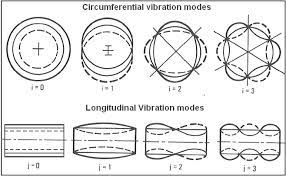

mega=10^6;
K_0             =4*pi*E_c*h_c*mm*L_i*mm/D_c*mm/mega     % [Mn/m] =10^6*N/m   % lumped Stiffness of breathing mode
M_0             =M_c*k_md                    % Lumped Mass 

#### Eq 5.8 mass addition factor for displacement [248]

k_md =1+(M_t+M_w+M_i)/M_c



Eq 5.9 $f_{0\;}$  `m = 0 Natural frequency of  circumferential mode`


$$f_0 =\frac{1}{\pi D_c }\sqrt{\frac{E_c }{\rho_c k_i k_{md} }}$$


`Eq 5.13  `$I_{c\;}$`moment of inertia `about the neutral axis parallel to the cylinder axis

 
$$$I_{c}=\frac{h_{c}^{3} L_{i}}{12}$$$


I_c=(h_c*mm)^3*L_i*mm/12;         % Moment of inertia                                                                          % eq 5.13 form in book


## `5.3 Improved analytical method of calculation of natural frequencies`

### `5.3.1 Natural Frequency of the stator core`

이 섹션에 제시된 분석적 접근 방식은 권선, 치아, 특히 외부 프레임이 고정자 시스템의 자연 주파수에 미치는 영향을 고려하려는 시도이다. 이 방법에서는 고정자 코어, 권선, 치아, 그리고 프레임은 별도로 모델링됩니다. 그런 다음 시스템에 대한 공식이 제안됩니다.

#### `Eq (5.17) Natural frequency of the stator core `$\left(\frac{L_i }{D_c }\le 1\right),\textrm{Pancake}$ motor

관성의 면적 모멘트 $I_c$가 링 축과 평행한 중성 축에 대해 방정식 5.13, h_c 고정자 멍에 두께, M_c단위 둘레당 질량에 의해 주어진다.


freq_m = zeros(length(m_values), 1);

for i = 1:length(m_values)
    m = m_values(i);
    freq_m(i) = calcFreqm517Hoppe(m, E_c, I_c, rho_l, D_c*mm);
end

table_m_freq = table(m_values', freq_m, 'VariableNames', {'m', 'freq_m'});
disp(table_m_freq);

#### `eq (5.18) the mass per unit circumference`


$$\rho_l =\frac{M_c }{\pi D_c }=\rho_c \left(\pi D_c \right)L_i h_c \frac{1}{\pi D_C }=\rho_c L_i h_c$$


rho_l               =(M_c)/(pi*D_c*mm)
% rho_l               =rho_c*L_i*mm*h_c*mm
rho_l               =massDensityCore*L_i*mm*ThicknessYoke*mm



#### `Eq (5.19)finite length cylinder - Lumped stiffness and `

#### `Eq 5.20 Lumped mass `

for i = 1:length(m_values)
    m = m_values(i);
    % Lumped Stiffness 
     % K_m = calcK519m(E_c, I_c, D_c, m); % Lumped Stiffness
    K_m(i)=calcK527m(Omega_m,D_c*mm,L_i*mm,h_c,E_c,v_c)  
    % Lumped Mass
end 

그러나, Hoppe의 방정식은 $L_i/D_c>=1$

이면 좋은 결과를 제공하지 않는다. 전기 기계의 고정자가 무한한 길이의 원통형 껍질로 간주되면 더 나은 결과를 얻을 수 있다. 대부분의 기계 공학 교과서에서, 원주 진동 모드 m ≥ 0에 대한 무한히 긴 쉘의 자연 주파수는 [135]로 표현된다.

#### Eq 5.21 Infinite Cylindrical Shell Natural Freuency


$$$f_m=\frac{\Omega_m}{\pi D_c} \sqrt{\frac{E_c}{\rho_c\left(1-v_c^2\right)}}$$$


freqm=calcFreqm521InfiniteShell(0.08,R_c*mm*2,E_c,rho_c,v_c)
D_c = 0.08 * sqrt(E_c / (rho_c * (1 - v_c^2)))/(464 * pi)
K2=4*0.08

K_m(3) = calcK525m(0.08,D_c,L_i*mm,h_c*mm,E_c, v_c); % Lumped Stiffness
M_c=8.58
freq=calcFreq56m(K_m(3),M_c)
freq=calcFreq56m(30918,52)

%non/rad*mm*(Pa=N/m^2)/(kg/m^3)
calc
%N·m / kg

Donnel-Mushtari 이론 [135]에 기초하여, 매개 변수 $\Omega_m$ -   2차 특성 운동 방정식해의 근은 다음과 같다:

Eq 5.22


$$\Omega_{0}=1$$


Eq 5.23


$$\Omega_{m}=\frac{1}{2} \sqrt{\left(1+m^{2}+\kappa^{2} m^{4}\right) \pm \sqrt{\left(1+m^{2}+\kappa^{2} m^{4}\right)^{2}-4 \kappa^{2} m^{6}}}$$


Eq 5.24


$$\kappa^{2}=\frac{h_{c}^{2}}{3 D_{c}^{2}}$$


% 5-22-24 in calcKapaa_squred, calsOmega522m


#### eq 5.25 Lumped Stiffness

Omega_mArr=[0 0]
for i = 1:length(m_values)
    m = m_values(i);
    kappa_squared = calcKappa524squared(h_c*mm, D_c*mm);
    Omega_m=calcOmega522m(m,kappa_squared);
    Omega_mArr=[Omega_mArr;Omega_m]
    % freq_m(i) = calcFreqm521InfiniteShell(Omega_m(i), D_c*mm, E_c, rho_c, v_c);
    % K_m(i) = calcK525m(Omega_m(i),D_c*mm,L_i*mm,h_c*mm,E_c*mm, v_c); % Lumped Stiffness
end
table_m_freq = table(m_values', freq_m,Omega_m', 'VariableNames', {'m', 'freq_m','Omega_m'});


Lumped Mass

$M_m =\pi \rho_c D_c L_i h_c$ 이는 실제로 고정자 코어 질량 $M_c$

이다. $L_i/D_c< 1$ 인 경우에도 방정식 5.21을 사용하는 것이 좋습니다.

(2극 기계(2p = 2)의 치아 뒤에 있는 고정자 코어(요크)는 다극기의 요크보다 더 두껍다. 따라서, 2극 기계의 Lumped Stiffness는 더 높고 고정자 코어의 deflection은은 극이 많은 기계보다 작다. 두 극 기계는 종종 다극 기계보다 덜 시끄러울 수 있다.)

### 5.3.2 Natural Frequency of a frame with end bells

엔드 벨이 있는 프레임(인클로저)은 양쪽 끝이 기계적으로 제한된 원형 원통형 쉘로 작동한다. 수학적으로, 양쪽 끝은 대략 단순히 지지되거나 고정되는 것으로 묘사될 수 있다. 원주 모달 패턴이 그림 2.9에 설명됨에 따라, 단순히 지지되는 끝이 있는 원형 원통형 껍질의 전형적인 축 모달 패턴은 그림 5.3에 나와 있다.

축 진동 모드는 n = 1, 2, 3 이다.

양쪽 끝에서 단순히 지지되는 조건을 가진 유한 길이 Lf의 닫힌 원형 원통형 껍질의 경우, 특징적인 운동 방정식은 다음과 같은 형태를 갖는다 [135]

#### eq 5.26


$$\Omega_{mn}^6 -\left(C_2 +\kappa \Delta C_2 \right)\Omega_{mn}^4 +\left(C_1 +\kappa \Delta C_1 \right)\Omega_{mn}^2 -\left(C_0 +\kappa \Delta C_0 \right)=0$$



$$\Omega _{mn}^3 - (C_2 + \kappa  * \Delta C_2) * \Omega _{mn}^2 + (C_1 + \kappa  * \Delta C_1) * \Omega _{ mn} - (C_0 + \kappa  * \Delta C_0) = 0$$


syms Omega_mnSqred;

% Preallocate arrays for lambda, C2, C1, and C0
lambda = zeros(1, length(n_values));
C2 = zeros(length(m_values), length(n_values));
C1 = zeros(length(m_values), length(n_values));
C0 = zeros(length(m_values), length(n_values));
for n = 1:length(n_values)
    % lambda(n) = calcLambda531(n_values(n), R_f/mm, L_f/mm);
    L_0(n)=calcLengthClampShell532(L_f,n)
    lambda_equ(n) = calcLambdaEqu532(n_values(n), R_f/mm, L_f/mm,L_0(n));

end

% Calculate C2, C1, and C0 for each m and n
kappa_squaredFrame=0.000246
for i = 1:length(m_values)
    m = m_values(i);
    for n = 1:length(n_values)
        [C2(i, n), C1(i, n), C0(i, n)] = calcCoeffi527to9(m, lambda_equ(n), v_f, kappa_squaredFrame);
    end
end

% Define the characteristic equation
% Initialize cell array to store solutions for each combination of m and n
solutions = cell(length(m_values), length(n_values));
Abssolutions = cell(length(m_values), length(n_values));


% Find roots for each combination of m and n
for i = 1:length(m_values)
    m = m_values(i);
    for n = 1:length(n_values)
        % Define the characteristic equation
        equation = Omega_mnSqred^3 - (C2(m + 1, n) + sqrt(kappa_squared) * DeltaC2) * Omega_mnSqred^2 + (C1(m + 1, n) + sqrt(kappa_squared) * DeltaC1) * Omega_mnSqred - (C0(m + 1, n) + sqrt(kappa_squared) * DeltaC0);
        % equation = Omega_mnSqred^3 - C2(i, n) * Omega_mnSqred^2 + C1(i, n)* DeltaC1 * Omega_mnSqred - C0(i, n)==0;

        % Solve the equation for Omega_mn
        sol = vpasolve(equation, Omega_mnSqred);

        % Store the solutions for the current combination of m and n
        solutions{i, n} = sol;
        Abssolutions{i,n}=abs(min(sol))
        % Display the roots of the third-order characteristic equation for the current combination of m and n
        disp(['Solutions for m = ', num2str(m), ', n = ', num2str(n), ':']);
        disp(sol);

    end
end



이것은 실제로 비차원 주파수 매개 변수와 관련하여 3차 방정식이다. 세 셋트의 근은 세 직교 방향의 진동에 해당하며, 가장 작은 실수 근은 프레임의 굴곡 진동의 자연 주파수와 관련이 있다. 도넬-무슈타리 이론에 따르면, 방정식 5.26의 상수는 [135]이다.

#### eq 5.27

### 
$$C_2 =1+\frac{1}{2}\left(3-v_f \right)\left(m^2 +\lambda^2 \right)+\kappa^2 {\left(m^2 +\lambda^2 \right)}^2$$


#### eq 5.28


$$C_1 =\frac{1}{2}\left(1-v_f \right)\left\lbrack \left(3+2v_f \right)\lambda^2 +m^2 +{\left(m^2 +\lambda^2 \right)}^2 \frac{3-v_f }{1-v_f }\kappa^2 {\left(m^2 +\lambda^2 \right)}^2 \right\rbrack$$


#### eq 5.29


$$C_0 =\frac{1}{2}\left(1-v_f \right)\left\lbrack \left(1-v_f^2 \right)\lambda^4 +\kappa^2 {\left(m^2 +\lambda^2 \right)}^4 \right\rbrack$$


% mxn matrix (circum x axial)
for i = 1:length(m_values)
    m = m_values(i);
    for n=1:length(n_values)
    [C_2(m+1,n), C_1(m+1,n), C_0(m+1,n)] = calcCoeffi527to9(m, lambda(n), v_f, kappa_squared);
    end
end


일반 코드

% Preallocate arrays for lambda, C2, C1, and C0
lambda = zeros(1, length(n_values));
C2 = zeros(length(m_values), length(n_values));
C1 = zeros(length(m_values), length(n_values));
C0 = zeros(length(m_values), length(n_values));

% Calculate lambda for each n
for n = 1:length(n_values)
    % lambda(n) = calcLambda531(n_values(n), R_f/mm, L_f/mm);
    L_0(n)=calcLengthClampShell532(L_f,n)
    lambda_equ(n) = calcLambdaEqu532(n_values(n), R_f/mm, L_f/mm,L_0(n));

end

% Calculate C2, C1, and C0 for each m and n
kappa_squaredFrame=0.000246
for i = 1:length(m_values)
    m = m_values(i);
    for n = 1:length(n_values)
        [C2(i, n), C1(i, n), C0(i, n)] = calcCoeffi527to9(m, lambda_equ(n), v_f, kappa_squaredFrame);
    end
end

% Initialize cell array to store solutions for each combination of m and n
solutions = cell(length(m_values), length(n_values));

% Find roots for each combination of m and n
for i = 1:length(m_values)
    m = m_values(i);
    for n = 1:length(n_values)
        % Define the characteristic equation as a third-order polynomial
        coeffs = [1, 0, -(C2(i, n) + sqrt(kappa_squaredFrame) * DeltaC2), (C1(i, n) + sqrt(kappa_squaredFrame) * DeltaC1), -(C0(i, n) + sqrt(kappa_squaredFrame) * DeltaC0)];
        
        % Solve the equation for Omega_mnSqred using roots function
        sol = roots(coeffs);

        % Store the solutions for the current combination of m and n
        solutions{i, n} = sol;
        
        % Display the roots of the third-order characteristic equation for the current combination of m and n
        disp(['Solutions for m = ', num2str(m), ', n = ', num2str(n), ':']);
        disp(sol);
    end
end

display Omega value

Omega_mnSqredCell = cell(length(m_values), length(n_values));

% Perform the last part for each solution cell
for i = 1:length(m_values)
    m = m_values(i);
    for n = 1:length(n_values)
        % Retrieve the solutions for the current combination of m and n
        sol = solutions{i, n};
        Abssolutions{i,n}=abs(solutions{i,n})
        % Display the solutions for the current combination of m and n
        % disp(['Solutions for m = ', num2str(m), ', n = ', num2str(n), ':']);
        % disp(sol);
        
        % Perform the desired operation for each solution
        for j = 1:length(sol)
            Omega_mnSqred_val = sol(j);
            
            % Evaluate the characteristic equation with the current Omega_mnSqred value
            eq_value = Omega_mnSqred_val^3 - (C2(i, n) + sqrt(kappa_squaredFrame) * DeltaC2) * Omega_mnSqred_val^2 + (C1(i, n) + sqrt(kappa_squaredFrame) * DeltaC1) * Omega_mnSqred_val - (C0(i, n) + sqrt(kappa_squaredFrame) * DeltaC0);
            % solutions	9×3 cell	9×3	cell
            % Display the value of Omega_mnSqred and the corresponding equation value
            disp(['m ',num2str(m) ,'n',num2str(n)]);
            disp(['Value of Omega_mnSqred ', num2str(j), ': ', num2str(Omega_mnSqred_val)]);
            % disp(['Equation value for Omega_mnSqred ', num2str(j), ': ', num2str(eq_value)]);
            disp('----------------------------------');
        end
    end
end


#### eq 5.30


$$\Delta C_2 =\Delta C_1 =\Delta C_0 =0$$


% Define functions for the coefficients
% C_2, ΔC_2, C_1, ΔC_1, C_0, and ΔC_0
DeltaC2 =0    % Define the function for ΔC_2
DeltaC1 =0    % Define the function for ΔC_1
DeltaC0 =0    % Define the function for ΔC_0



#### eq 5.31


$$\lambda =n\pi \frac{R_f }{L_f };~~R_f =0\ldotp 5\left(D_f -h_f \right);~~\kappa^2 =\frac{h_f^2 }{12R_f^2 }$$



kappa_squared = calcKappa531squared(h_f, R_f);
R_f = calcMeanRadiusFrame(D_f, h_f);
lambda=zeros(length(n_values),1)
for n=1:length(n_values)
    lambda(n) = calcLambda531(n, R_f, L_f);
end

여기서 $\nu _f$는 푸아송 비율이고, $R_f$는 평균 프레임 반경, $D_f$는 외부 프레임 직경, $h_f$는 프레임 두께, $L_f$는 프레임 길이이다.

프레임의 양쪽 끝이 모두 고정될 때, 특성 방정식 5.26은 여전히 유효하며, 방정식의 상수는 방정식 5.27-식. 5.30에 표시된 것과 동일하다.

러나, 방정식 5.26은 아놀드와 워버튼에 따르면 $\lambda _e$로 대체된 방정식 5.31의 매개 변수 λ로 해결되어야 한다.[135]

#### eq 5.32


$$\lambda_e =n\pi \frac{R_f }{L_f -L_0 };~~L_0 =L_f \frac{0\ldotp 3}{n+0\ldotp 3}$$


% Calculate lambda for each n
for n = 1:length(n_values)
    % lambda(n) = calcLambda531(n_values(n), R_f/mm, L_f/mm);
    L_0(n)=calcLengthClampShell532(L_f,n)
    lambda_equ(n) = calcLambdaEqu532(n, R_f/mm, L_f/mm,L_0(n));

end

여기서 $L_0$은 축 모달 번호 n에 의존하는 "클램프 클램프" 쉘의 길이에 대한 보정이다. "클램프 클램프" 쉘 또는 양쪽 끝에서 단순히 지원되는 쉘의 경우, 원주 진동 모드 m = 0, 1, 2, 3, . . . 각 축 진동 모드 n = 1, 2, 3, . . . 축 모드 n = 0은 존재하지 않는다.

따라서, 프레임의 고유 주파수는

#### eq 5.33


$$f_{mn} =\frac{1}{2\pi }\frac{\Omega_{mn} }{R_f }\sqrt{\frac{E_f }{\rho_f \left(1-v_f^2 \right)}}=\frac{1}{2\pi }\sqrt{\frac{K_{mn} }{M_f }}$$


여기서 $E_f$는 프레임 재료의 탄성 계수이고, $\rho _f$는 재료 밀도이다. 그러므로 프레임의 덩어리 뻣뻣함은

#### eq 5.34


$$K_{mn} =\frac{\Omega_{mn}^2 }{R_f^2 }\frac{E_f V_f }{1-v_f^2 }=\frac{2\Omega_{mn}^2 }{R_f }\frac{\pi L_f h_f E_f }{1-v_f^2 }$$


#### eq 5.35


$$M_f =\rho_f V_f =\rho_f \left(2\pi R_f \right)L_f h_f ;~~V_f =2\pi R_f L_f h_f$$


### 5.3.3 Natural Frequency of Stator Core -Frame System

대부분의 전기 기계에는 고정자 코어가 프레임(클로저)으로 눌러져 있다. 프레임은 고정자의 질량과 강성을 모두 증가시킨다. 고정자 코어가 짧으면 $h_c$, 외부 구조는 고정자 코어 전체에 균일하게 전달되는 압력을 생성한다. 동축 실린더의 결과 관성 모멘트 $I_c resultant$는 각 실린더의 관성 모멘트의 합과 같기 때문에, 고정자 프레임 시스템의 자연 주파수는 고정자 코어 Lumped Stiffness $K_m^{(c)}$와 

$K_{mn}^{(f)}$ 은 병렬이라는 가정하에서 등가 Lumped Stiffness는 $K_m^{(c)}+K_{mn}^{(f)}$로 가정한다.

고정자 코어와 프레임의 동등한 질량에 대해 동일한 가정이 이루어진다. 즉, 고정자 프레임 시스템의 결과 질량은 $$M_c+M_f$$이다.

이러한 가정하에, 고정자 프레임 시스템의 자연 주파수는 아래와 같이 표현될 수 있다:

#### eq 5.36


$$f_{mn} \approx \frac{1}{2\pi }\sqrt{\frac{K_m^{(c)} +K_{mn}^{(f)} }{M_c +M_f }}$$


[1]See also S. Huang, M. Aydin, and T. A. Lipo, Electromagnetic vibration and noise assessment for surface mounted PM machines, IEEE PES Summer Meeting, Vol. 3, pp. 1417–1426, Vancouver, BC, Canada, 2001

대형 기계에서 소음을 생성하는 고정자 코어의 deflection은 약 $\pm 0\ldotp 25\times 10^{-4}$mm [220]이다. 반면에, 코어의 외경과 프레임의 내경 사이의 제조 공차는 ±0.02에서 ±0.1mm이다. 이것은 코어와 프레임 사이의 기계적 커플링이 낮은 진폭 deflection을 주기에는 작다는 것을 의미한다[220]. 스탬프가 찍힌 링 라미네이션이 있는 소형 기계는 대형 기계의 세그먼트 라미네이션보다 기계적 커플링이 발생할 가능성이 더 높다. 코어와 프레임 사이의 기계적 커플링은 가열 후 방사형 팽창으로 인해 증가한다. 대부분의 전기 기계 건설에 대한 소음과 진동 계산에서,

- 프레임은 대형 기계에서만 무시될 수 있습니다;

- 프레임과 관성 모멘트는 작은 기계에서 무시할 수 없습니다.

### 5.3.4 Effect of the stator winding and teeth

권선은 강판치로 분리된 슬롯내에 있다. 권선이 있는 치 슬롯 구역은 고정자 코어(요크) 내부의 추가적인 링으로 간주될 수 있다. 따라서, 권선이 있는 고정자 프레임 시스템의 자연 주파수는 다음과 같다.

#### eq 5.37


$$f_{mn} \approx \frac{1}{2\pi }\sqrt{\frac{K_m^{(c)} +K_{mn}^{(f)} +K_m^{(w)} }{M_c +M_f +M_w }}$$


% K_mc = 100;
% K_mn_f = 200;
% K_m_w = 300;
% M_c = 10;
% M_f = 20;
% M_w = 30;

for i = 1:length(m_values)
    m = m_values(i);
    % Am(i) = calcAm(Fm(i), M_shell, w_m(i), w_r, zeta_m(i));
    kappa_squared=0.0074;
    Omega_m(i)=calcOmega522m(m,kappa_squared)
    K_m_w(i) = calcK539infiniteWind(Omega_m(i), R_w, E_w, v_w, v_w);
    f_mn(i,j) = calcfreq537windTeeth(K_mc(i), K_mn_f, K_m_w(i), M_c, M_f, M_w);
end

disp(f_mn);


여기서 $K_m^{\left(w\right)}$은 권선을 포함한 치 슬롯 영역의 lumped stiffness이며 M_w는 치, 권선 및 단열재의 질량이다. 치 슬롯 구역의 lumped stiffness이며은 섹션 5.3.1에 명시된 방법에 따라 결정될 수 있다

짧은 길이의 와인딩 (유한 길이 실린더)

#### eq 5.38


$$K_m^{(w)} =\frac{m^2 \left(m^2 -1\right)}{m^2 +1}\frac{2\pi E_w I_w }{R_w^3 }$$


% 
% m=2
% 
% K_m_w = calcK538shortwind(m, E_w, I_w, R_w);
% disp(K_m_w);


긴 길이 와인딩용(무한하게 긴 실린더)

#### eq 5.39


$$K_m^{(w)} =\frac{\Omega_m^2 }{R_w^2 }\frac{E_w V_w }{1-v_w^2 }$$


% Omega_m = 10;
%temporary
% R_w = 0.5*(D_1in*mm+h_t*mm) 
% R_w=0.5*(0.16 + 0.028)
% E_w =9.4 *10^9 %[Pa] (copper, insulation, encapsulation )
print('Poisson ratio of laminations νc',v_c)
print('Poisson ratio of winding',v_w)

for i = 1:length(m_values)
    m = m_values(i);
    % Am(i) = calcAm(Fm(i), M_shell, w_m(i), w_r, zeta_m(i));
    kappa_squared=0.0074;
    Omega_m(i)=calcOmega522m(m,kappa_squared)
    K_m_w(i) = calcK539infiniteWind(Omega_m(i), R_w, E_w, v_w, v_w);
end


비차원 주파수 매개 변수 $\Omega_m$는  $R_w =R_c -h_{\textrm{sl}}$에 대해 방정식 5.22와 5.23에 따른다. 

여기서 $R_c$는 The mean radius of the stator core (yoke)

$R_w$ 는  mean radius of the stator winding

여기서 $h_{sl}
$는 슬롯 깊이, $$V_w= 2\pi R_wh_t(L_i+ 2_{hov}) $$ 는 실린더로 간주되는 권선의 부피, $L_i$는 고정자 스택의 유효 길이, $h_{ov}$는 단면 끝 결선의 축방향 길이이며,$E_{w}
$는 권선 및 절연물을 구리 권선용 탄성 계수이며 $ v_w$는 프아송 비율이다. 탄성계수는  110~120 GPa이며 폴리머 절연물은 3 GPa입니다. 슬롯 충전 인자 0.5정도라고 가정하면 구리와 절연물에 대한 등가 탄성 계수는 약 9.4 GPa [241]이다. 구리의 푸아송 비율은 0.33에서 0.36이며 폴리머 단열재는 0.36을 초과합니다. 권선 덩어리의 무게는

#### eq 5.40 (motorcad weight calc로부터 가져오기)


$$M_w =m_1 \rho_w N_1 l_{turn} a_w a_p s_w$$


% m1 = 2;
% N_1 = 10;
% l_turn = 5;
% a_w = 0.2;
% a_p = 0.5;
% s_w = 0.8;

% M_w = calcM540m(m1, rho_w, N_1, l_turn, a_w, a_p, s_w);
% disp(M_w);
M_w=11.45
